% Create the B-Spline
degree = 3;
xMin = 0;
xMax = 1;
nElem = 4;
continuity = 2;

splineSpace.degree = degree;
splineSpace.uniqueKnotsVector = linspace(xMin,xMax,nElem+1);
splineSpace.continuityVector = [-1 continuity*ones(1,nElem-1) -1];
BSpline = bspline(splineSpace);

BSpline.decomposition.globalExtractionOperator

$$ans = \left(\begin{array}{ccccccccccccc} 1 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 1 & \frac{1}{2} & \frac{1}{4} & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & \frac{1}{2} & \frac{7}{12} & \frac{2}{3} & \frac{1}{3} & \frac{1}{6} & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & \frac{1}{6} & \frac{1}{3} & \frac{2}{3} & \frac{2}{3} & \frac{2}{3} & \frac{1}{3} & \frac{1}{6} & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & \frac{1}{6} & \frac{1}{3} & \frac{2}{3} & \frac{7}{12} & \frac{1}{2} & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & \frac{1}{4} & \frac{1}{2} & 1 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1 \end{array}\right)$$

[~,GA] = BSpline.computeGrevilleAbscissae

$$GA = \left(\begin{array}{c} 0\\ \frac{1}{12}\\ \frac{1}{4}\\ \frac{1}{2}\\ \frac{3}{4}\\ \frac{11}{12}\\ 1 \end{array}\right)$$

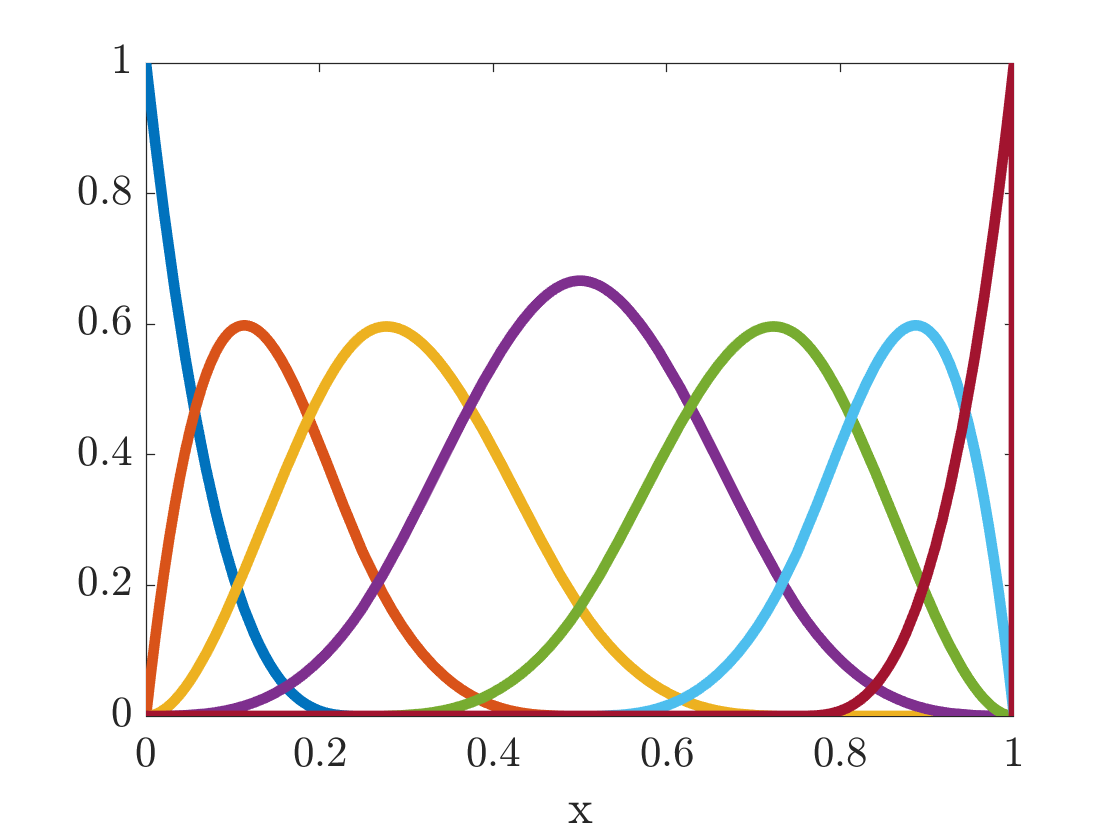


figure
fplot(BSpline.basis.functions,[0 1],"LineWidth",4,"Clipping","on","ShowPoles","off")
xlabel("x","Interpreter","latex")
ax = gca;
ax.FontSize = 16;
ax.ClippingStyle = "rectangle";
ax.TickLabelInterpreter = "latex";

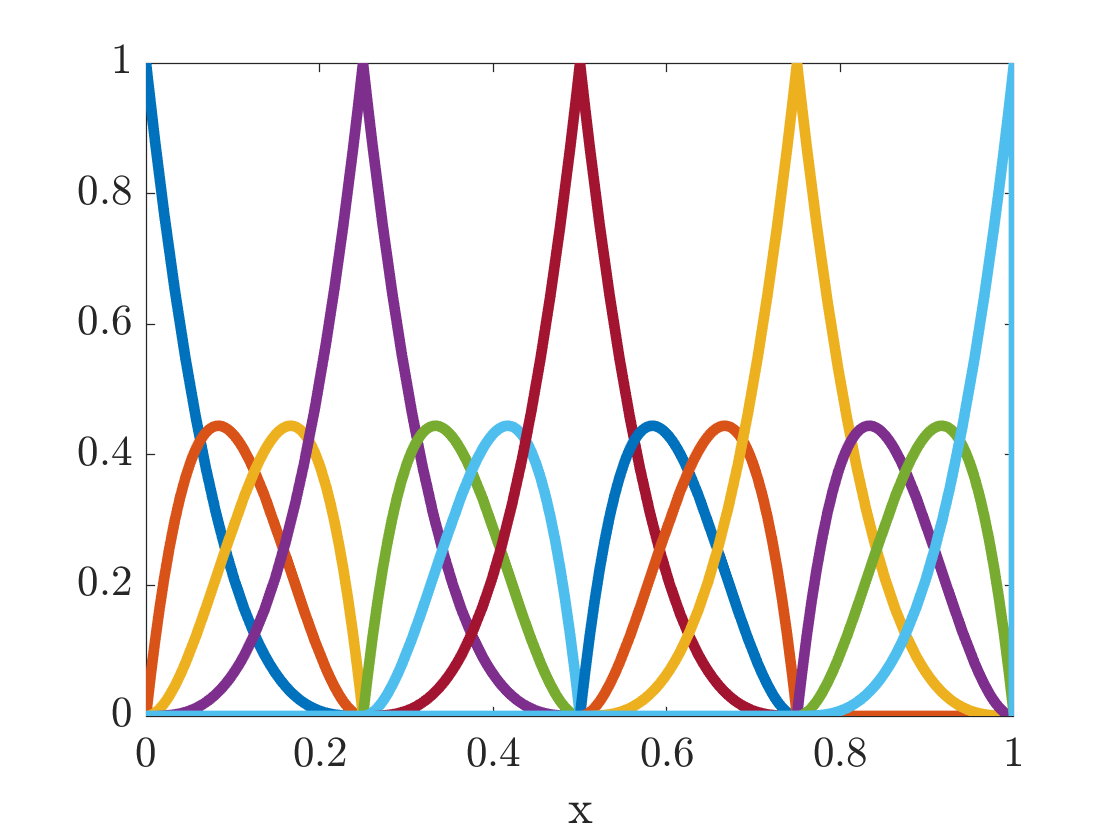


figure
fplot(BSpline.decomposition.spline.basis.functions,[0 1],"LineWidth",4,"Clipping","on","ShowPoles","off")
xlabel("x","Interpreter","latex")
ax = gca;
ax.FontSize = 16;
ax.ClippingStyle = "rectangle";
ax.TickLabelInterpreter = "latex";

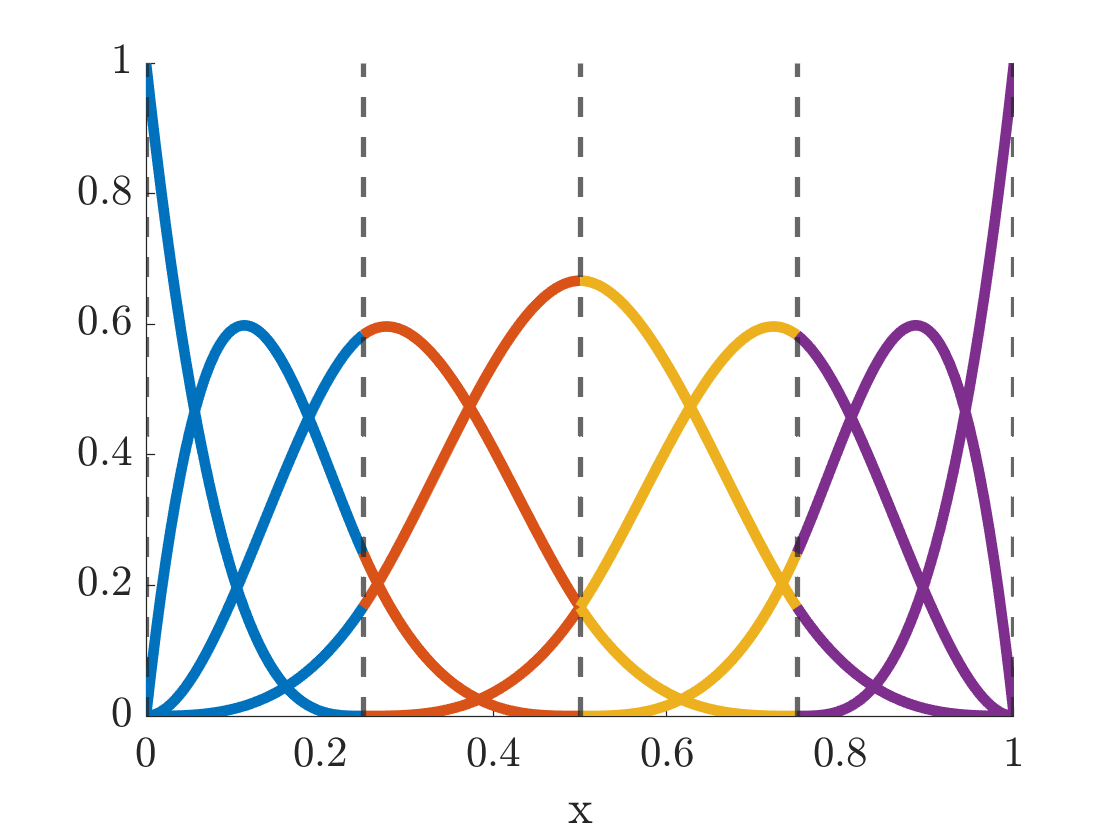

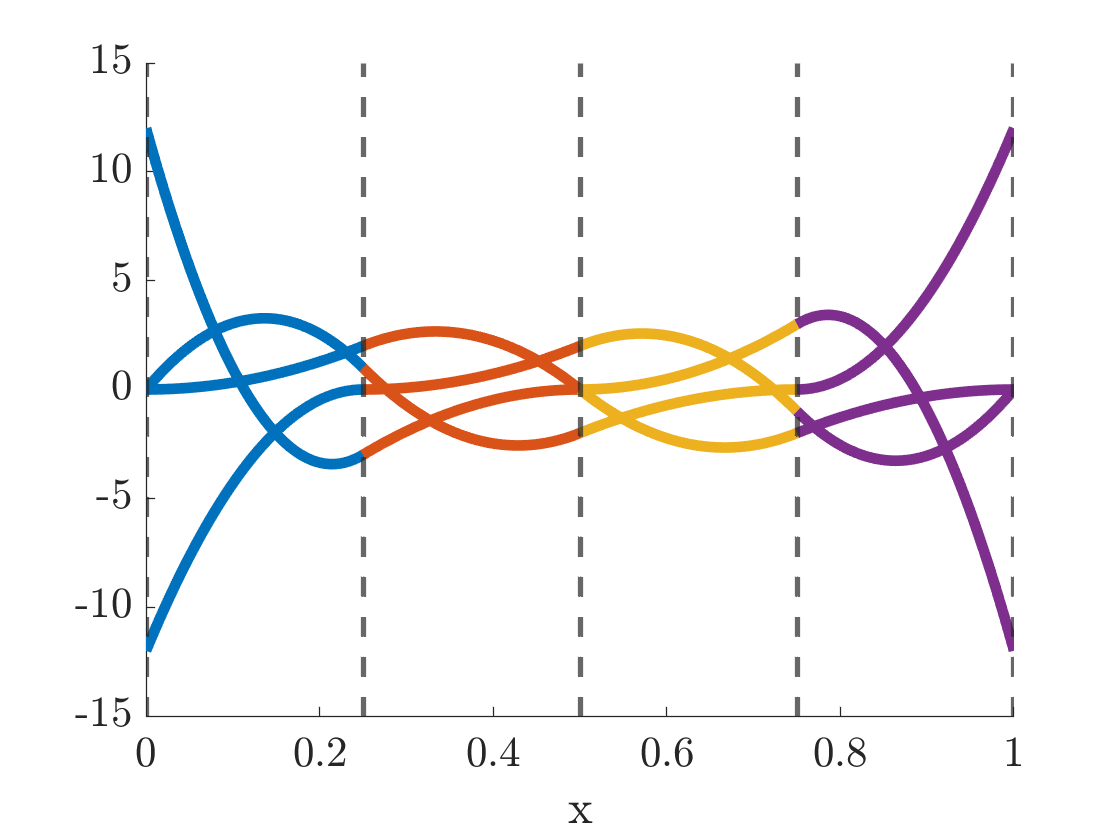

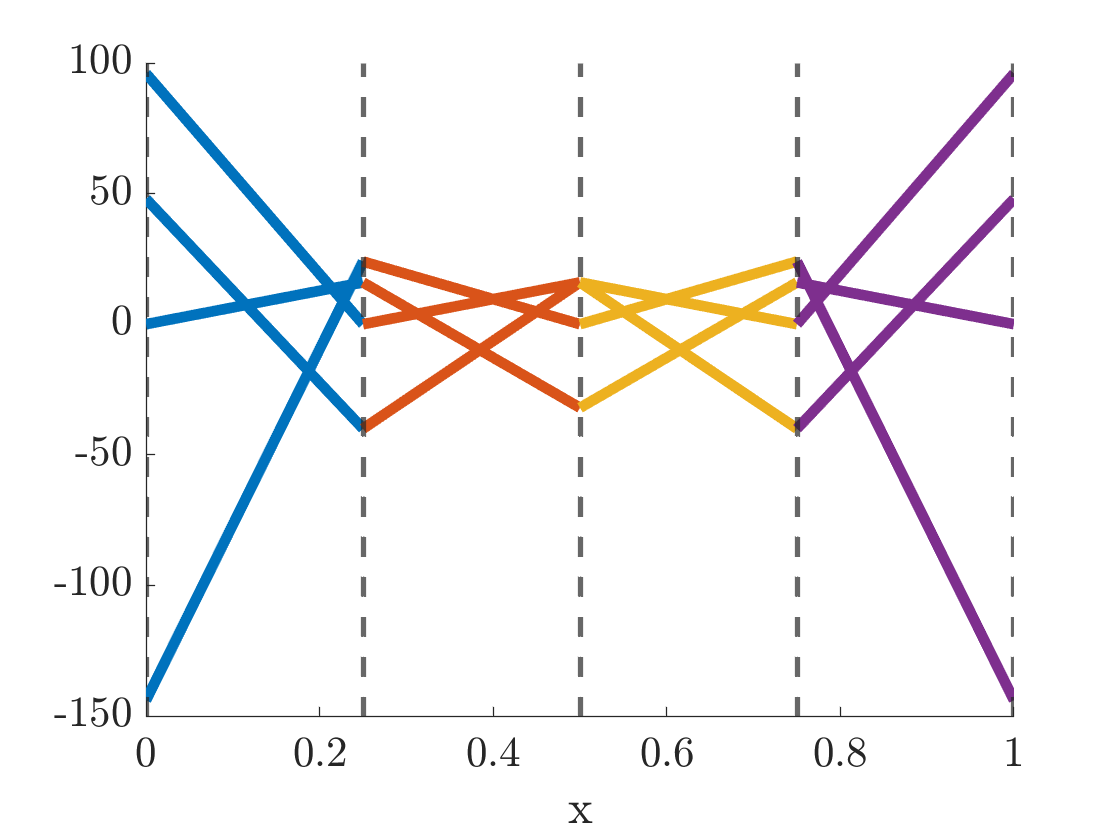

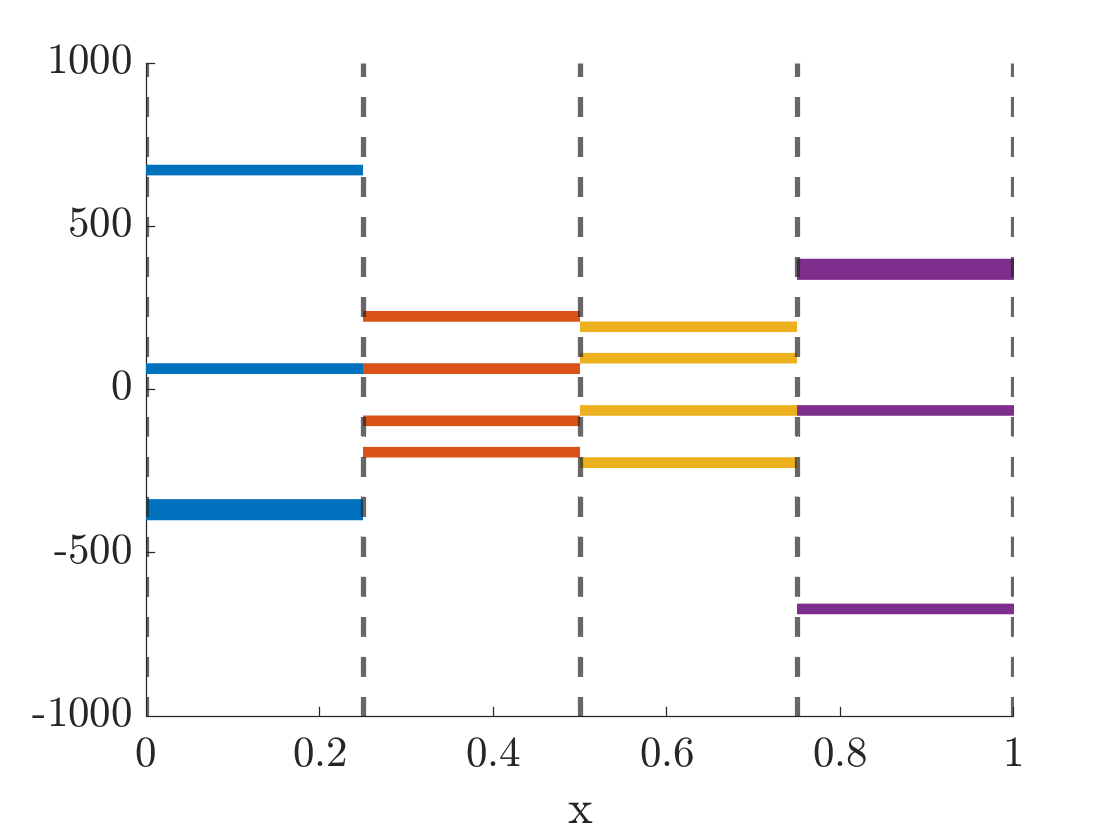

C = BSpline.decomposition.localExtractionOperator;
bFunMap = BSpline.decomposition.localExtractionSupportedBezierBases;
bezFun = BSpline.decomposition.spline.basis.functions;
bezNodes = BSpline.uniqueKnotsVector;

for ii = 0:BSpline.degree
    figure
    cmap = colormap("lines");
    hold on
    for e = 1:length(C)
        f = diff(C{e} * bezFun(bFunMap{e}),ii);
        fplot(f,[bezNodes(e)+1e-6 bezNodes(e+1)-1e-6],"Color",cmap(e,:),"LineWidth",4)
        if e == 1
            xline(bezNodes(e),"LineWidth",2,"LineStyle","--");
            xline(bezNodes(e+1),"LineWidth",2,"LineStyle","--");
        else
            xline(bezNodes(e+1),"LineWidth",2,"LineStyle","--");
        end
    end
    xlabel("x","Interpreter","latex")
    ax = gca;
    ax.FontSize = 16;
    ax.ClippingStyle = "rectangle";
    ax.TickLabelInterpreter = "latex";
end

## Mesh

cmap = colormap("Lines");

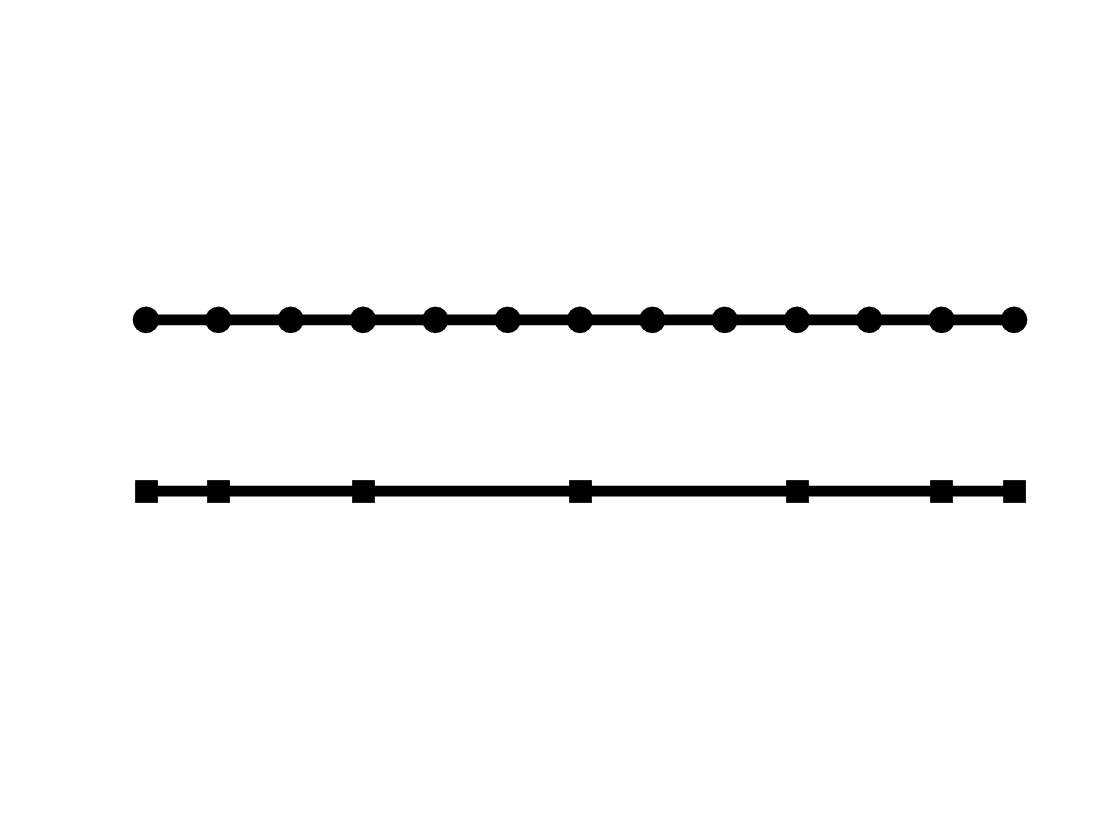

figure
hold on
plot(BSpline.decomposition.spline.nodes, ones(size(BSpline.decomposition.spline.nodes)),'-ko',"MarkerFaceColor",'k',"LineWidth",4,"MarkerSize",6)
plot(BSpline.nodes, -ones(size(BSpline.nodes)),'-ks',"MarkerFaceColor",'k',"LineWidth",4,"MarkerSize",6)
ylim([-4 4])
axis off

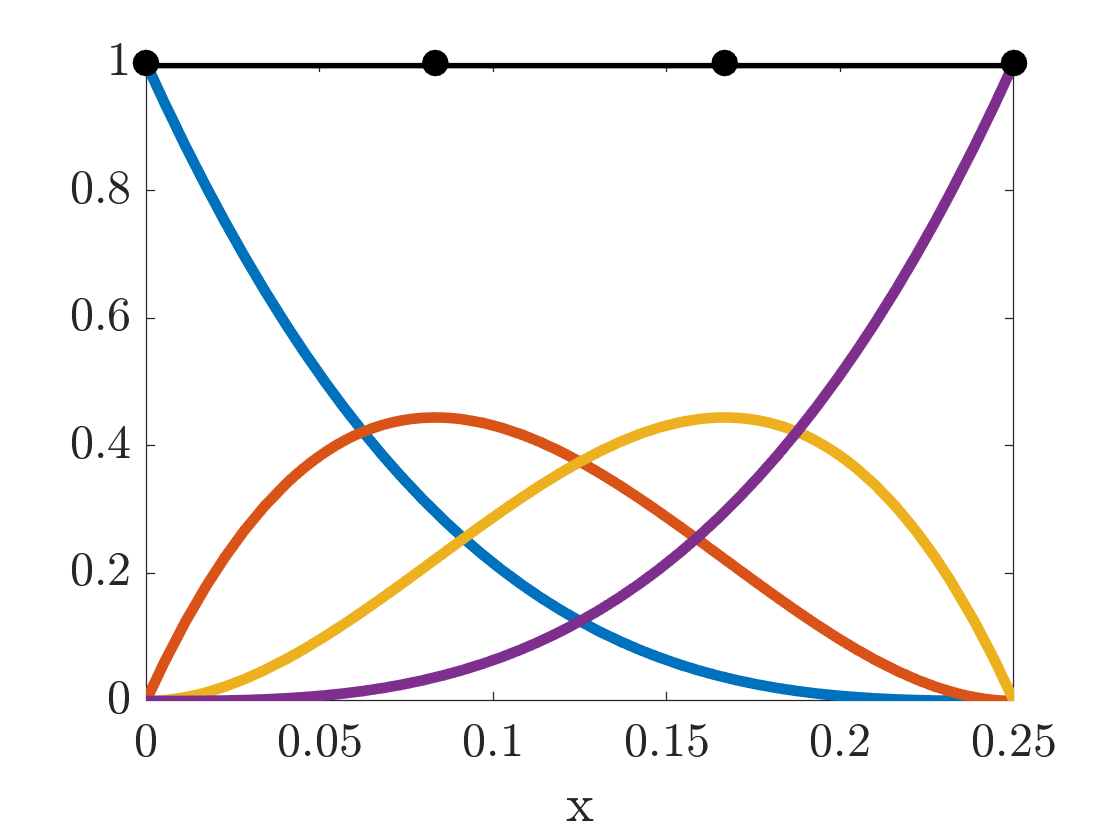

figure
% subplot(2,1,1)
hold on
f = bezFun(bFunMap{1});
x = BSpline.decomposition.spline.nodes(BSpline.decomposition.localExtractionSupportedBezierBases{1});

fplot(f,[BSpline.uniqueKnotsVector(1) BSpline.uniqueKnotsVector(2)],"LineWidth",4,"Clipping","on","ShowPoles","off")
plot(x,ones(size(x)),"LineWidth",4,"Color","k","Marker","o","MarkerFaceColor","k","MarkerEdgeColor","k","MarkerSize",6)
xlim([BSpline.uniqueKnotsVector(1) BSpline.uniqueKnotsVector(2)])
xlabel("x","Interpreter","latex")
ax = gca;
ax.Box = "on";
ax.Clipping = "on";
ax.ClippingStyle = "rectangle";
ax.FontSize = 18;
ax.TickLabelInterpreter = "latex";

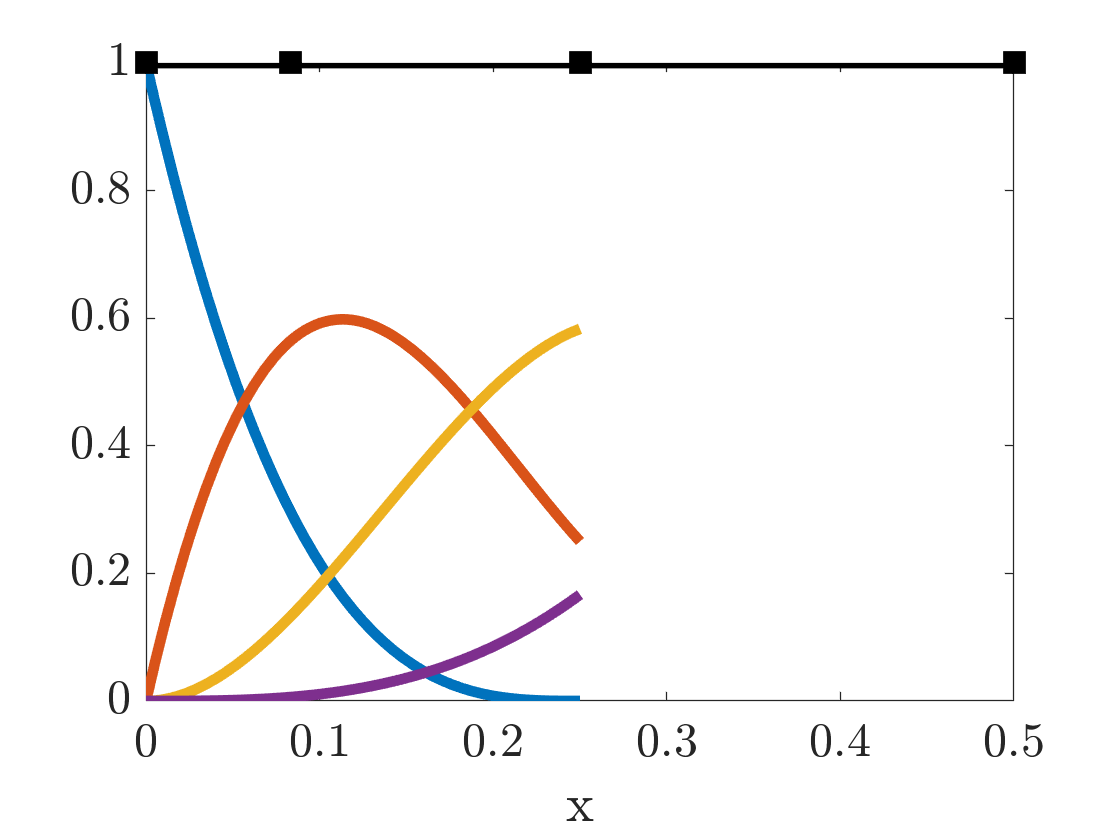



% subplot(2,1,2)
figure
hold on
f = C{1} * bezFun(bFunMap{1});
x = BSpline.nodes(BSpline.decomposition.localExtractionSupportedSplineBases{1});
fplot(f,[BSpline.uniqueKnotsVector(1) BSpline.uniqueKnotsVector(2)],"LineWidth",4,"Clipping","on","ShowPoles","off")
plot(x,ones(size(x)),"LineWidth",4,"Color","k","Marker","s","MarkerFaceColor","k","MarkerEdgeColor","k","MarkerSize",6)
xlabel("x","Interpreter","latex")
ax = gca;
ax.Box = "on";
ax.Clipping = "on";
ax.ClippingStyle = "rectangle";
ax.FontSize = 18;
ax.TickLabelInterpreter = "latex";